# **Robot Model**

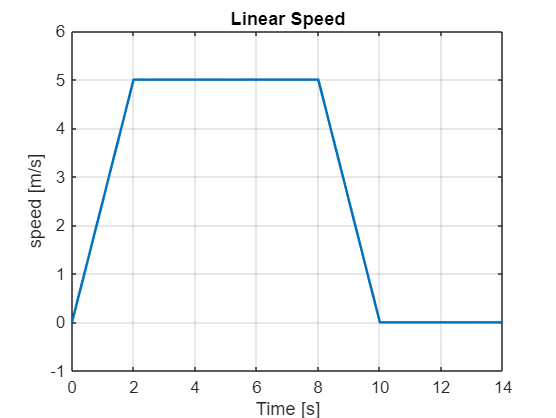

clear;
clc;
Ts = 0.2;
% Distance to Point P
l = 1;

% Delta Time
delta_t = Ts;
% Time
t = 0:delta_t:10+20*Ts;

% Trapezoidal Speed
speed_max = 5;
v = speed_max/2*ramp(t) - speed_max/2*ramp(t-2) - speed_max/2*ramp(t-8) + speed_max/2*ramp(t-10);

% Speed Plot
figure;
plot(t, v, 'LineWidth', 1.5);
grid on;
xlabel('Time [s]');
ylabel('speed [m/s]');
title('Linear Speed');

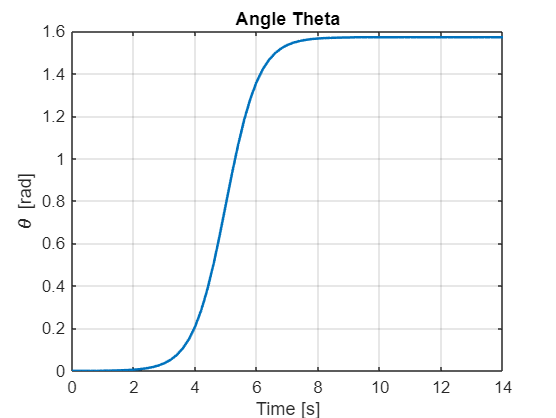

% Parameters
theta_0 = 0;          % [rad]
theta_f = pi/2;         % [rad]
t_start_turn = 1;          % Turn start [s]
t_end_turn = 9;             % Turn end [s]
k = 15;                     % sigmoid slope

% Angle
theta_ref = zeros(size(t));

for i = 1:length(t)
    if t(i) < t_start_turn
        % Before starting the turn, we keep the same heading
        theta_ref(i) = theta_0;
    elseif t(i) > t_end_turn
        % After the end of the turn, we keep the same heading
        theta_ref(i) = theta_f;
    else
        % in the turn we use a sigmoid
        tau = (t(i) - t_start_turn) / (t_end_turn - t_start_turn);  % time normalization
        theta_ref(i) = theta_0 + (theta_f - theta_0) / (1 + exp(-k * (tau - 0.5)));
    end
end

% Plot of the heading angle
figure;
plot(t, theta_ref, 'LineWidth', 1.5);
grid on;
xlabel('Time [s]');
ylabel('\theta [rad]');
title('Angle Theta');

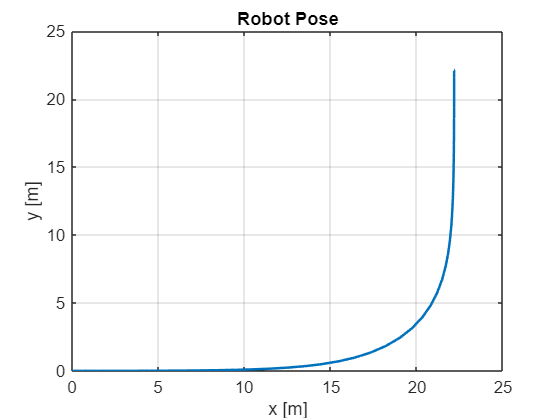

% Initial Position
x0 = 0;
y0 = 0;

% Trajectory of the Robot
pose = zeros(2, length(t));
pose(:,1) = [x0 y0]';

for i = 2:length(t)
    % Update x
    pose(1, i) = pose(1, i-1) + v(i)*cos(theta_ref(i))*delta_t;
    % Upate y
    pose(2, i) = pose(2, i-1) + v(i)*sin(theta_ref(i))*delta_t;
end

figure()
plot(pose(1,:), pose(2,:), 'LineWidth', 1.5);
grid on;
xlabel('x [m]');
ylabel('y [m]');
title('Robot Pose');

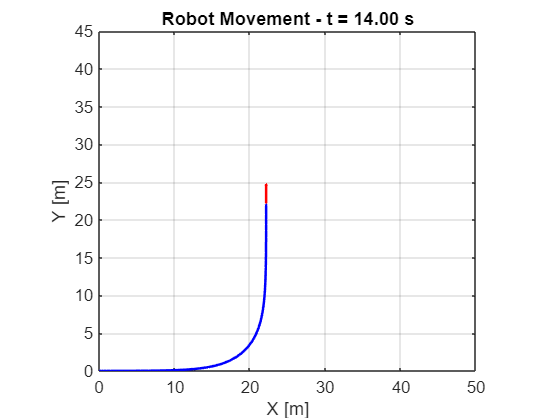

figure;
for i = 1:length(t)
    plot(pose(1,1:i), pose(2,1:i), 'b', 'LineWidth', 1.5); hold on; % Path traversed
    quiver(pose(1,i), pose(2,i), cos(theta_ref(i)), sin(theta_ref(i)), 2.5, 'r', 'LineWidth', 1.5);
    axis equal;
    grid on;
    xlabel('X [m]');
    ylabel('Y [m]');
    xlim([0,50]);
    ylim([0,45])
    title(sprintf('Robot Movement - t = %.2f s', t(i)));
    drawnow;
    hold off;
end

## MPC Test

% Control Signal
n = 2;
n_u = 2;

% Control Horizon
N = 10;

u = zeros(n_u, length(t) - N);
x_history = zeros(n, length(t) - N +1);

% Control Matrices
Q = 5*eye(2);
R = eye(2);
P = 10*eye(2);

% Robot Parameters
d = 0.5;    % Distance between Wheels [m]
r = 0.25;   % Wheel Radius [m]
robot_params = [d, l, r];

% Initial Pose
xk = [x0 y0]';
x_history(:,1) = xk;

for i = 1:length(u)
    % First we take the useful parameters of the trajectory
    poseRef = pose(:, i:i+N);
    thetaRef = theta_ref(1, i:i+N);
    % Computing the control signals
    u(:,i) = FHOCP(xk, Q, R, P, N, n, n_u, delta_t, poseRef, thetaRef, robot_params);
    % Updating the State
    [xk, yk] = model_Robot_pointP(xk, u(:,i), delta_t);
    % States
    x_history(:,i+1) = xk;
end


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit https://github.com/coin-or/Ipopt
******************************************************************************

------------------------------------
 La Pose Actual 
     0
     0

 El angulo ref 
    1.3688
   -0.0000

------------------------------------
 La Pose Actual 
    0.2738
   -0.0000

 El angulo ref 
    1.5520
    0.0000

------------------------------------
 La Pose Actual 
    0.5842
   -0.0000

 El angulo ref 
    1.8422
    0.0000

------------------------------------
 La Pose Actual 
    0.9526
    0.0000

 El angulo ref 
    2.1987
   -0.0000

------------------------------------
 La Pose Actual 
    1.3924
    0.0000

 El angulo ref 
    2.5935
   -0.0000

------------------------------------
 La 

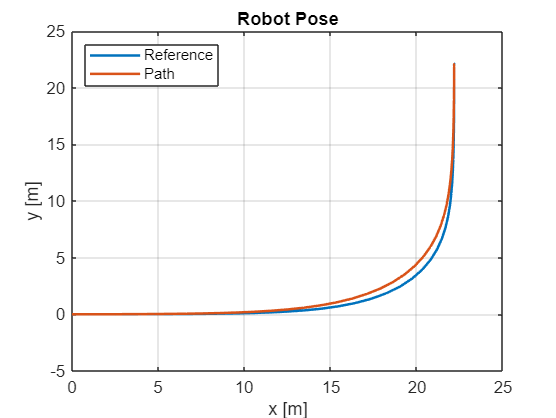


figure()
plot(pose(1,:), pose(2,:), 'LineWidth', 1.5);
hold on;
plot(x_history(1,:), x_history(2,:), 'LineWidth', 1.5);
grid on;
xlabel('x [m]');
ylabel('y [m]');
title('Robot Pose');
legend('Reference', 'Path', Location='northwest')

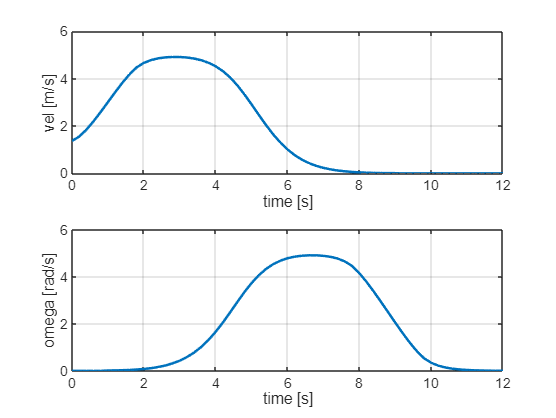


figure()
subplot(2,1,1)
plot(t(1,1:length(u)), u(1,:), 'LineWidth', 1.5);
grid on;
xlabel('time [s]');
ylabel('vel [m/s]');
subplot(2,1,2)
plot(t(1,1:length(u)), u(2,:), 'LineWidth', 1.5);
grid on;
xlabel('time [s]');
ylabel('omega [rad/s]');



pose_time = [t', pose'];
theta_time = [t', theta_ref'];


function x = ramp(t)
    x = t.*(t>=0);
end